# PART 1

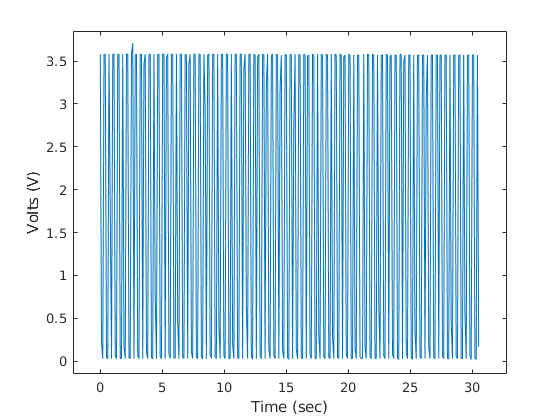


% read data example: Import columns as column vectors 
data = csvread('newfile.csv');%, 'columns', {'X, 'Y', 'Z'});

% Plot the imported data and label the graph correctly
time = data(:,1)/1000;
volts = data(:,2);
plot(time,volts)
xlabel('Time (sec)')
ylabel('Volts (V)')

xlim([-2.2 32.8])
ylim([-0.15 3.85])


% Use findpeaks function and create new time_peaks array for plotting
y = data(:,2)';
[pks,locs] = findpeaks(y);

pks =     3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.7100    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5800    3.5700    3.5800    3.5800    3.5800    3.5800    3.5800    3.5700    3.5800    3.5800    3.5800    3.5800


locs =      4     8    11    15    19    22    27    30    33    37    40    44    47    51    55    58    62    65    69    73    76    80    84    88    91    95    98   102   106   109   113   117   120   124   128   131   135   139   142   146   149   153   157   160   164   168   171   175   178   182


time_peaks = [];
for e = locs
    time_peaks = [time_peaks time(e)];
end
 
% Frequency
freq = length(pks)/time(end)

freq = 2.7198

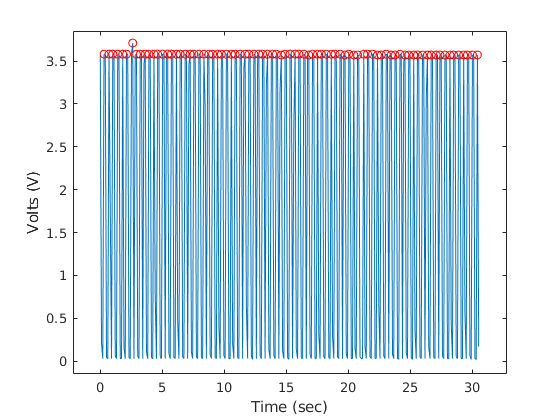


% Plot peaks with original plot
plot(time,volts)
xlabel('Time (sec)')
ylabel('Volts (V)')
xlim([-2.2 32.8])
ylim([-0.15 3.85])
hold on
plot(time_peaks,pks, 'or')


% Using Noisey Signal example
% Y = fft(pks);
% 
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% 
% f = Fs*(0:(L/2))/L;
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of X(t)')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')
